### This links with `plot_interpolation_template.mlx` (for comparison between regression and interpolation)

Data 

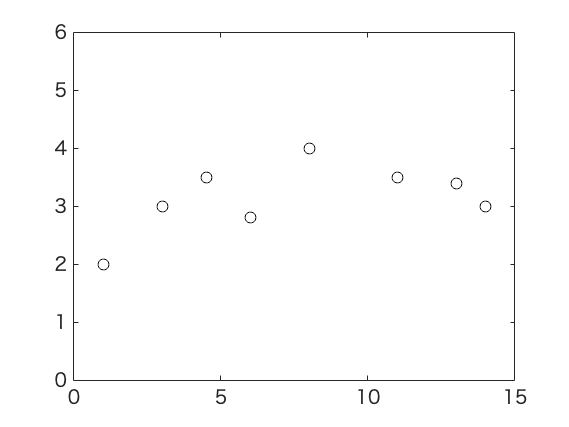

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

figure
plot(x,y , 'ko')
hold on
axis([0, 15, 0, 6])
hold off

Linear regression

p1 = polyfit(x, y, 1)

p1 =     0.0610    2.6890


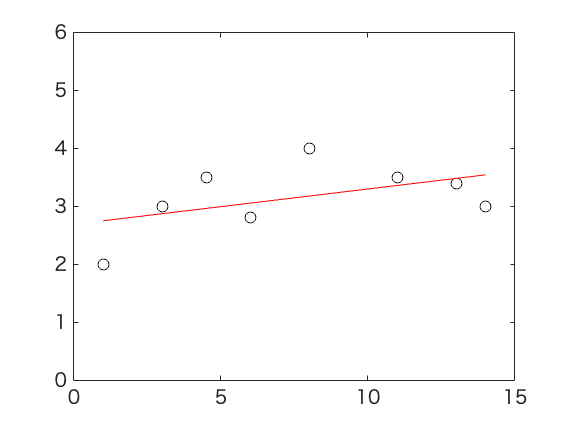


xx = 1:0.1:14;
yy1 = polyval(p1, xx);

figure
plot(x,y , 'ko')
hold on
plot(xx, yy1, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Quadratic polynomial regression

p2 = polyfit(x, y, 2)

p2 =    -0.0249    0.4460    1.6919


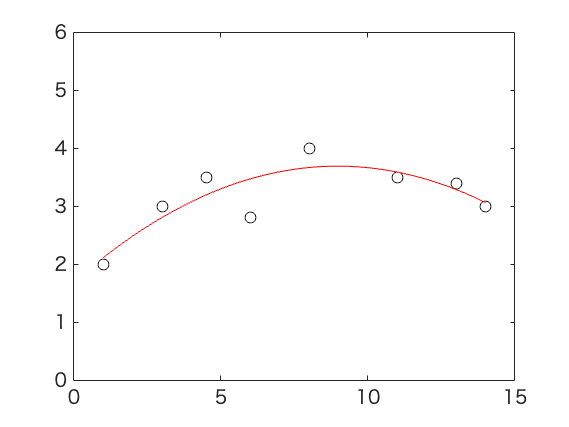


xx = 1:0.1:14;
yy2 = polyval(p2, xx);

figure
plot(x,y , 'ko')
hold on
plot(xx, yy2, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Cubic polynomial regression

p3 = polyfit(x, y, 3)

p3 =     0.0002   -0.0292    0.4714    1.6582


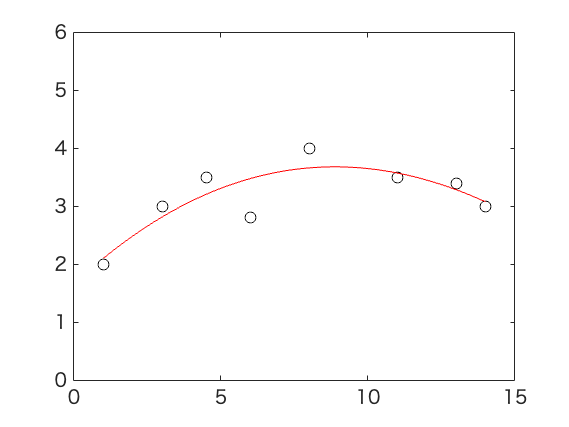


xx = 1:0.1:14;
yy3 = polyval(p3, xx);

figure
plot(x,y , 'ko')
hold on
plot(xx, yy3, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

6th-order polynomial regression

p6 = polyfit(x, y, 6)

p6 =    -0.0000    0.0023   -0.0446    0.4324   -2.1232    4.9823   -1.2651


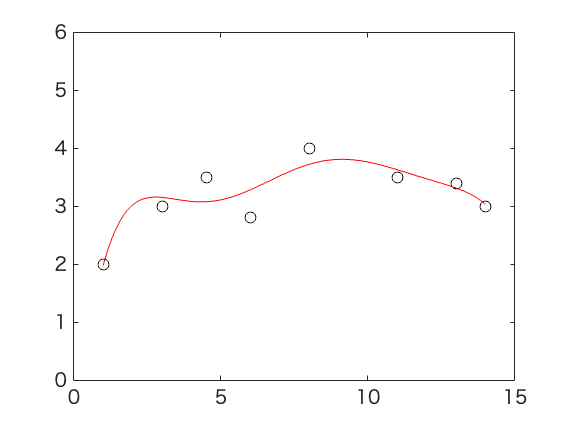


xx = 1:0.1:14;
yy6 = polyval(p6, xx);

figure
plot(x,y , 'ko')
hold on
plot(xx, yy6, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

7th-order polynomial regression

p7 = polyfit(x, y, 7)

p7 =    -0.0001    0.0048   -0.1036    1.1597   -7.0728   22.8676  -34.5103   19.6548


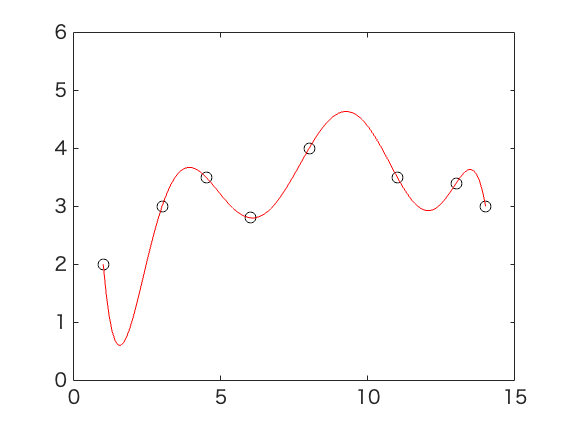


xx = 1:0.1:14;
yy7 = polyval(p7, xx);

figure
plot(x,y , 'ko')
hold on
plot(xx, yy7, 'r-')
hold on
axis([0, 15, 0, 6])
hold off


% notice that the line passes through all points,
% this is *now* actually an interpolated curve!
% compare this with the last graph in plot_interpolation_template.mlx
% both are the same graph